clear all
clc
syms x(t) y(t) theta(t) T(t) m L g

animate_it = 1;     % set to 1 to plot the animation
save_it = 0;        % set to 1 to save the animation

paramVals.m=4; paramVals.L=3; paramVals.g=-9.81;
m=4; L=3; 

rG=[x(t);y(t)];

%F=ma for top arm
eq1=m*diff(rG,t,t)==T(t)*[-sin(theta(t));cos(theta(t))]-m*g*[0;1];

%Keep bob on circular path at distance L from the pivot
eq2=rG+L*[-sin(theta(t));cos(theta(t))]==[0;0];

DES=[eq1];
disp_const=[eq2];
vel_const = [];



[DEs, PPs]=generateGoveringDEs(DES,disp_const,vel_const,[theta,diff(theta)])

The unknown functions are:
T(force)
theta
x
y

Expected Number of State Variables:2


$$DEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{g\,\sin\left(\theta \left(t\right)\right)}{3\,\left({\cos\left(\theta \left(t\right)\right)}^{2}+{\sin\left(\theta \left(t\right)\right)}^{2}\right)}$$

$$PPs = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=3\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{\sin\left(\theta \left(t\right)\right)\,\sigma_{1}}{\sigma_{4}+\sigma_{3}}\\ \frac{\partial }{\partial t}y\left(t\right)=3\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\frac{3\,{\cos\left(\theta \left(t\right)\right)}^{3}\,\sigma_{2}+3\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}\,\sigma_{2}-g\,\sigma_{3}}{\sigma_{4}+\sigma_{3}}\\ T\left(t\right)=\frac{4\,\sigma_{1}}{\sigma_{4}+\sigma_{3}}\\ x\left(t\right)=3\,\sin\left(\theta \left(t\right)\right)\\ y\left(t\right)=-3\,\cos\left(\theta \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\sigma_{4}\,\sigma_{2}+3\,\sigma_{3}\,\sigma_{2}+g\,\cos\left(\theta \left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}={\sin\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{4}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

specificDEs=subs(DEs,paramVals);
specificPPs=subs(PPs,paramVals);

The unknown functions (just the base functions, not derivatives) are: theta(t)


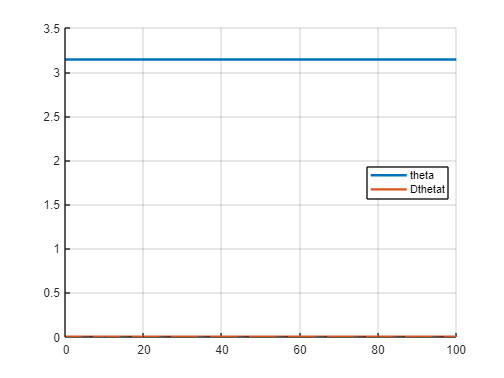

soln=timeStepODESystem(specificDEs,[0,100],[theta==pi; diff(theta)==0],specificPPs);

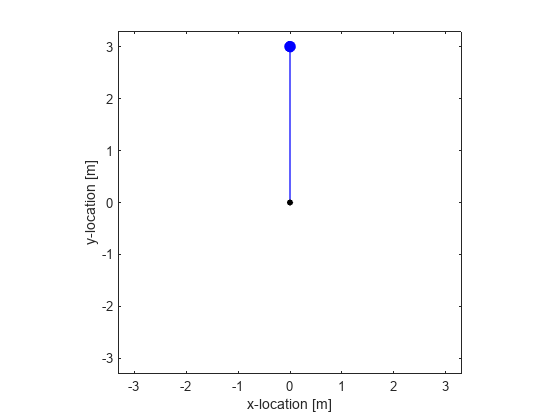

if animate_it == 1
    t_anim = linspace(min(soln.t),max(soln.t),201)';
    theta_anim = interp1(soln.t,soln.theta,t_anim);
    func_animate_double_pendulum(t_anim,theta_anim,L,save_it)
end

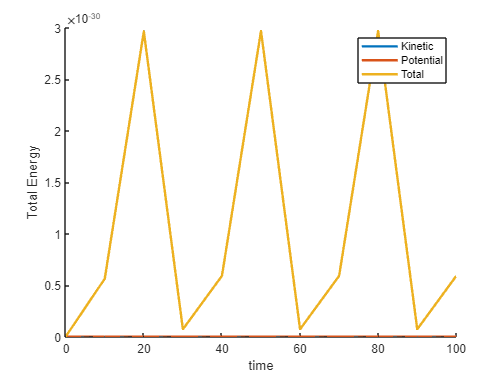

KineticEnergy=subs(1/2*m*(soln.Dxt.^2+soln.Dyt.^2),paramVals);
PotentialEnergy=subs(m*soln.y*g - m*soln.y(1)*g,paramVals);
figure
clf
hold on
plot(soln.t,KineticEnergy,'LineWidth',2)
plot(soln.t,PotentialEnergy,'LineWidth',2)
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')
legend('Kinetic','Potential','Total')

function [] = func_animate_double_pendulum(t,theta,L,save_it)

skip_frame = 1;

if save_it == 1
    %--------------------------------------------------------------------------
    % animate the results
    saveDirName = uigetdir('', ['Specify the directory where the ', ...
        'animations will be saved.']);

    %  Append a slash to the directory name ('/' for Mac, '\' for Windows):
    if isempty(strfind(saveDirName, '/')) == 0
        saveDirName = [saveDirName, '/'];
    else
        saveDirName = [saveDirName, '\'];
    end

    animObj = VideoWriter([saveDirName, 'bob_pendulum.avi']);
    open(animObj)
    skip_frame = 5;
end

% plot the angular displacements
figure(1)
clf
plot(0,0)
xlabel('x-location [m]')
ylabel('y-location [m]')
axis equal
axis([-1.1*L 1.1*L -1.1*L 1.1*L])

for k = 1:length(t)

    R_a_I = [sin(theta(k)) cos(theta(k)) 0;-cos(theta(k)) sin(theta(k)) 0;0 0 1];

    rPx(k,1) = 0;
    rPy(k,1) = 0;

    temp = R_a_I*[L;0;0];
    rGx(k,1) = temp(1);
    rGy(k,1) = temp(2);
end

%  Draw pendulums, joints, and CGs
pend = line('xdata', [rPx(1) rGx(1)], 'ydata', [rPy(1) rGy(1)],...
    'color','b','linewidth',1);
pointP = line('xdata', rPx(1), 'ydata', rPy(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 4);
pointG = line('xdata', rGx(1), 'ydata', rGy(1), ...
    'marker', 'o', 'color', 'b', 'markerfacecolor', 'b', 'markersize', 8);
pathG = line('xdata', rGx(1:1), 'ydata', rGy(1:1), ...
    'color', 'b', 'linewidth', 1, 'linestyle',':');

for k = 1:skip_frame:length(t)
    set(pend, 'xdata', [rPx(k) rGx(k)], 'ydata', [rPy(k) rGy(k)]);
    set(pointG,'xdata', rGx(k), 'ydata', rGy(k));
    set(pathG,'xdata', rGx(1:k), 'ydata', rGy(1:k));
    drawnow

    if save_it == 1
        writeVideo(animObj, getframe(gcf));
    end
end

if save_it == 1
    close(animObj)
end
end
